hour = 3600;
testFrequency = 0.1;
T0 = 1350;
day = 24*hour;
PKEStartTime = 3*day;
simIn = Simulink.SimulationInput('MSREPrimaryLoop_PlantLevel');
simIn = setModelParameter(simIn, StopTime = '500000');
%simIn = setModelParameter(simIn, StopTime = '260000');
%simIn = setModelParameter(simIn, StopTime = '259200.1');
simOut = sim(simIn);

frequencyReactivityTable = timeseries2timetable(simOut.frequencyReactivity);
neutronDensityTable= timeseries2timetable(simOut.neutronDensity);
frequencyReactivitySignal = frequencyReactivityTable.Data;
neutronDensitySignal = neutronDensityTable.Data;
frequencyReactivitySignal = frequencyReactivitySignal(PKEStartTime*10+1:end);
neutronDensitySignal = neutronDensitySignal(PKEStartTime*10+1:end)-1;
[autoSignal,fa] = cpsd(frequencyReactivitySignal,frequencyReactivitySignal,[],[],logspace(-4,0,500),10);

Error using signal.internal.spectral.welchparse>segment_info (line 298)
The input record needs more than eight samples in order to use the default window and overlap.

Error in signal.internal.spectral.welchparse (line 34)
[L,noverlap,win]

[crossSignal,fc] = cpsd(frequencyReactivitySignal,neutronDensitySignal,[],[],logspace(-4,0,500),10);

%plot(fc,abs(crossSignal./autoSignal))
plot(fc*2*pi,abs(crossSignal./autoSignal))
figure
plot(fc*2*pi,-(angle(crossSignal)-angle(autoSignal))/pi*180)

testFrequency = 0.1;
minNumberOfCycles = 20;
minimumTime = 1000;
testTime = max(minimumTime,minNumberOfCycles*2*pi/testFrequency);

hour = 3600;
T0 = 1400;
day = 24*hour;
PKEStartTime = 3*day;

SimEndTime = num2str(PKEStartTime + testTime);

simIn = Simulink.SimulationInput('MSREPrimaryLoop_PlantLevel');
simIn = setModelParameter(simIn, StopTime = SimEndTime);
simIn.InitialState = InitialState;

simOutFreq = sim(simIn);

frequencyReactivityTable = timeseries2timetable(simOutFreq.frequencyReactivity);
neutronDensityTable= timeseries2timetable(simOutFreq.neutronDensity);
frequencyReactivitySignal = frequencyReactivityTable.Data;
neutronDensitySignal = neutronDensityTable.Data - 1;
frequencyReactivitySignal = frequencyReactivitySignal(floor(2*pi/testFrequency*10):end);
neutronDensitySignal = neutronDensitySignal(floor(2*pi/testFrequency*10):end);
[autoSignal,fa] = cpsd(frequencyReactivitySignal,frequencyReactivitySignal,[],[],logspace(log10(testFrequency)-2,log10(testFrequency),151),10);
[crossSignal,fc] = cpsd(frequencyReactivitySignal,neutronDensitySignal,[],[],logspace(log10(testFrequency)-2,log10(testFrequency),151),10);
[SignalPower,PeakIndex] = max(abs(autoSignal))
freqResponse = crossSignal(PeakIndex)./autoSignal(PeakIndex)
freqGain = abs(freqResponse);
freqPhase = angle(freqResponse)/pi*180;


meanOutletTemp = simOut.CoreOutletTemperature.Data(end)

meanOutletTemp = 919.9948

testFrequencyList = logspace(-3,0,91);
%testFrequencyList = [1e-4,3e-4,7e-4,testFrequencyList];
freqGainList = zeros(size(testFrequencyList));
%freqGainList = zeros(size(testFrequencyList));
freqPhaseList = zeros(size(testFrequencyList));
for i = 1:length(testFrequencyList)
    testFrequency = testFrequencyList(i);
    minNumberOfCycles = 11;
    minimumTime = 1500;
    testTime = max(minimumTime,minNumberOfCycles*2*pi/testFrequency);
    hour = 3600;
    T0 = 1350;
    day = 24*hour;
    PKEStartTime = 3*day;
    SimEndTime = num2str(PKEStartTime + testTime);
    simIn = Simulink.SimulationInput('MSREPrimaryLoop_PlantLevel');
    simIn = setModelParameter(simIn, StopTime = SimEndTime);
    simIn.InitialState = InitialState;
    simOutFreq = sim(simIn);
    frequencyReactivityTable = timeseries2timetable(simOutFreq.neutronDensity);
    neutronDensityTable= timeseries2timetable(simOutFreq.CoreOutletTemperature);
    frequencyReactivitySignal = frequencyReactivityTable.Data - mean(frequencyReactivityTable.Data);
    neutronDensitySignal = neutronDensityTable.Data - meanOutletTemp;
    frequencyReactivitySignal = frequencyReactivitySignal(floor(2*pi/testFrequency*10):end);
    neutronDensitySignal = neutronDensitySignal(floor(2*pi/testFrequency*10):end);
    [autoSignal,fa] = cpsd(frequencyReactivitySignal,frequencyReactivitySignal,[],[],logspace(log10(testFrequency)-2,log10(testFrequency),151),10);
    [crossSignal,fc] = cpsd(frequencyReactivitySignal,neutronDensitySignal,[],[],logspace(log10(testFrequency)-2,log10(testFrequency),151),10);
    %[SignalPower,PeakIndex] = max(abs(autoSignal));
    PeakIndex = 91;
    SignalPower= abs(autoSignal(PeakIndex));
    freqResponse = crossSignal(PeakIndex)./autoSignal(PeakIndex)
    freqGainList(i) = abs(freqResponse);
    freqPhaseList(i) = angle(freqResponse)/pi*180;
    disp(['Frequency:',num2str(testFrequency)]);
    disp(['Gain:',num2str(freqGainList(i))]);
    disp(['Phase:',num2str(freqPhaseList(i))]);
end

freqResponse = 23.7165 +28.9287i

Frequency:0.001


Gain:37.4077


Phase:50.6542


freqResponse = 21.6920 +28.1684i

Frequency:0.0010798


Gain:35.5528


Phase:52.4008


Simulation aborted

[signalSpec, fs] = pwelch(frequencyReactivitySignal,[],[],logspace(log10(testFrequency)-1,log10(testFrequency)+1,151),10);
[responseSepc, fr] = pwelch(neutronDensitySignal,[],[],logspace(log10(testFrequency)-1,log10(testFrequency)+1,151),10);

%figure()
plot(fc*2*pi,abs(crossSignal./autoSignal));
hold on
ax = gca;
ax.FontName = 'Times';
ax.FontSize = 18;
set(gca,'looseInset',[0 0 0 0.01]);
pbaspect([2 1 1]);
xlabel('Frequency, [Rad/s]');
ylabel('Gain, [-]');
xlim([0.01,1]);
ax.XScale = 'log';
ax.YScale = 'log';


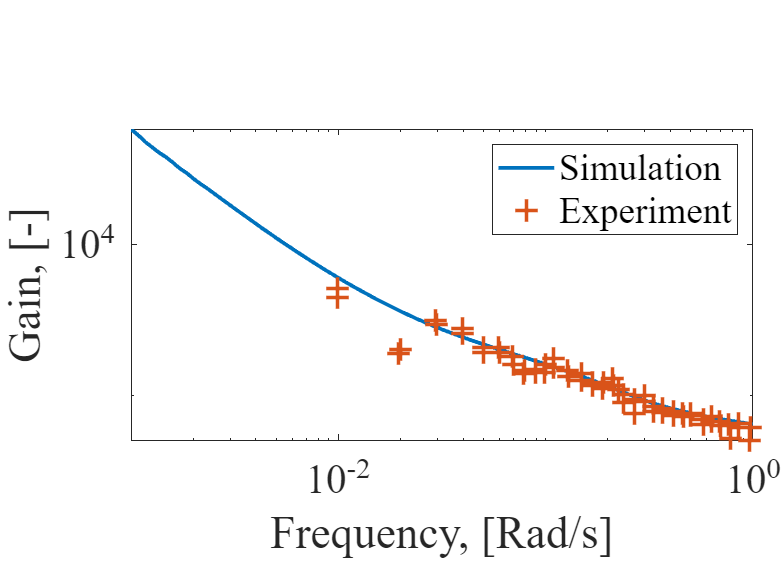

figure()
plot(testFrequencyList,freqGainList,'LineWidth',2,'DisplayName','Simulation');
hold on
plot(frequency0MWU233Gain_x,frequency0MWU233Gain_y,'LineWidth',2,'DisplayName','Experiment','LineStyle','none','Marker','+','MarkerSize',12)
ax = gca;
ax.FontName = 'Times';
ax.FontSize = 22;
set(gca,'looseInset',[0 0 0 0.01]);
pbaspect([2 1 1]);
xlabel('Frequency, [Rad/s]');
ylabel('Gain, [-]');
xlim([0.001,1]);
ax.XScale = 'log';
ax.YScale = 'log';
legend()

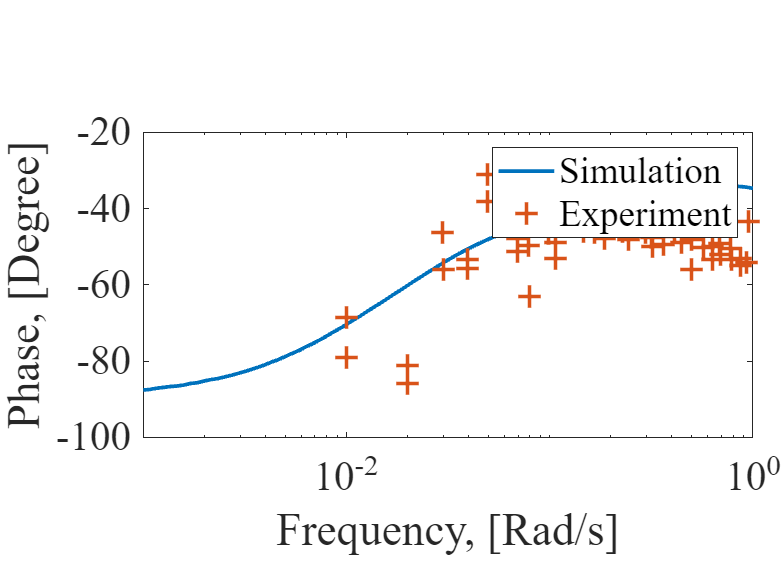

figure()
plot(testFrequencyList,-freqPhaseList,'LineWidth',2,'DisplayName','Simulation');
hold on
plot(frequency0MWU233Phase_x,frequency0MWU233Phase_y,'LineWidth',2,'DisplayName','Experiment','LineStyle','none','Marker','+','MarkerSize',12)
ax = gca;
ax.FontName = 'Times';
ax.FontSize = 22;
set(gca,'looseInset',[0 0 0 0.01]);
pbaspect([2 1 1]);
xlabel('Frequency, [Rad/s]');
ylabel('Phase, [Degree]');
xlim([0.001,1]);
ax.XScale = 'log';
legend()

neutronDensitySignal = simOut.neutronDensity.Data;
neutronDensitySignal = (neutronDensitySignal(2592000:2592000+4000) - 1)*1;
timeSignal = (0:length(neutronDensitySignal)-1)*0.1;